# 11D optimisation of droplet center

#### To generate optimisation procedure for the *(center of the)* initial droplet location

- Select variables for droplet and chose Target Shape

- Plot initial droplet shape based on chosen `x0`

- Use optimisation prosidure to find bes possition of droplet

**Looping erro**

- Set grid size to small value:` xMax = 10`

- If  |`x - x0`|` ~= x0`,   where   `x ≠ x0`

- Then `x_sol = x0 ~≠ x`

**Solution**

- make` xMax >> |x - x0|`

**Gradient distribution erro**

- If `|x - x0| `is too large,` TolX `is met 

- but` |x - x0| `is not close to zero

**Solution**

- Modifi ` costEvaluation...`

- Possibly to account for central difference

**or**

- Just have` x0 `sufficiently close to` x`

- `x0 `should be within targetshape rejion

clear; clc;

## **1) **

**Set some values**

y0 = .1084434390; % Raise droplet profile...
N = 120; % # sample points
A = 17; % Magnitude/Amplitude of droplet
% c1 = 0.0010;  
% c2 = 0.0196;
c1 = 0.0010;  
c2 = 0.0196;

c3 = 0.0013;
c4 = 0.0108;

tfinal = 10^5; % final time >> 1
xMax = 20; 
dx = 2*xMax/(N-1); % Stepsize
X = -xMax:dx:xMax; % Linespace/Mesh
k = 1/(2*xMax/N); %omega
% Possition / Shift
x0 = 7.5;
x = 10;
x1 = 15;
aa=-5;
bb=5;
cc=.5;

**Target Shape **`h_target`

a=round(aa/dx+N/2);
b=round(bb/dx+N/2);
c=cc*ones(size(X));

h_region = ones(size(X));
h_region(1:a) = c(1:a) + cc.*tanh((X(1:a)-aa)./(10));
h_region(a+1:(a+b)/2) = c(a+1:(a+b)/2) + (1+cc).*tanh((X(a+1:(a+b)/2)-aa)./(3));
h_region((a+b)/2+1:b) = c((a+b)/2+1:b) - (1+cc).*tanh((X((a+b)/2+1:b)-bb)./(3));
h_region(b+1:end) = c(b+1:end) - cc.*tanh((X(b+1:end)-bb)./(10));

target = [a,b,h_region];

## **2) **

**Solutions**

Inside

[tSpan,D1,D2,X,H0,myObjective,conds_Sol,...
    fval,exitflag,output,history,History,h_Sol,H_Sol,OUTS]...
    = SolutionRegion(tfinal,dx,X,k,y0,N,A,c1,c2,x0,target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          87.0698         
     1            4          86.7138         initial simplex
     2            6          84.0444         expand
     3            8          75.2862         expand
     4            9          75.2862         reflect
     5           11           65.559         expand
     6           13          53.1007         expand
     7           15          48.1721         expand
     8           16          48.1721         reflect
     9           18          46.7114         contract outside
    10           19          46.7114         reflect
    11           21          43.9964         reflect
    12           23          43.9964         contract inside
    13           25          43.1308         reflect
    14           27          43.1308         contract inside
    15           29          37.2591         expand
    16           30          37.2591         reflect
    17           32   


[~,~,~,~,H0_Possition,myObjective_Possition,conds_Sol_Possition,...
    ~,~,output_Possition,history_Possition,History_Possition,h_Sol_Possition,H_Sol_Possition,OUTS_Possition]...
    = SolutionPossition(tfinal,dx,X,k,y0,N,A,c1,c2,x0,target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          87.0698         
     1            2          87.0698         initial simplex
     2            4          80.4952         expand
     3            6          61.1921         expand
     4            8          18.0336         expand
     5           10          12.0617         reflect
     6           12          12.0617         contract inside
     7           14          11.6703         contract inside
     8           16          11.6703         contract inside
     9           18          11.6703         contract inside
    10           20          11.6703         contract outside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 

Elapsed time is 20.354502 seconds.



[~,~,~,~,H0_Disjoining,myObjective_Disjoining,conds_Sol_Disjoining,...
    ~,~,output_Disjoining,history_Disjoining,History_Disjoining,h_Sol_Disjoining,H_Sol_Disjoining,OUTS_Disjoining]...
    = SolutionDisjoining(tfinal,dx,X,k,y0,N,A,c1,c2,history_Possition(end),target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          11.6703         
     1            3          10.5731         initial simplex
     2            5          5.54498         expand
     3            7          2.03624         expand
     4            9          1.54525         reflect
     5           11          1.54525         contract outside
     6           13          1.49732         contract inside
     7           15          1.48416         reflect
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 

Elapsed time is 5.847024 seconds.



[~,~,~,~,H_2,~,conds_Sol_2,...
    ~,~,output_2,history_2,History_2,h_Sol_2,H_Sol_2,OUTS_2]...
    = SolutionRegion(tfinal,dx,X,k,y0,N,A,c1,c2,x,target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          91.9475         
     1            4          91.1176         initial simplex
     2            6          89.9461         expand
     3            8          88.2276         expand
     4           10          85.1027         expand
     5           12          78.8749         expand
     6           14          63.4086         expand
     7           16          55.3016         expand
     8           17          55.3016         reflect
     9           18          55.3016         reflect
    10           19          55.3016         reflect
    11           20          55.3016         reflect
    12           21          55.3016         reflect
    13           23          55.3016         contract outside
    14           28          55.3016         shrink
    15           33          55.3016         shrink
    16           34          55.3016         reflect
    17           39          55.3016    


[~,~,~,~,H_2Possition,~,conds_Sol_2Possition,...
    ~,~,output_2Possition,history_2Possition,History_2Possition,h_Sol_2Possition,H_Sol_2Possition,OUTS_2Possition]...
    = SolutionPossition(tfinal,dx,X,k,y0,N,A,c1,c2,x,target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          91.9475         
     1            2          91.9475         initial simplex
     2            4           91.217         expand
     3            6          84.0928         expand
     4            8           24.847         expand
     5           10          12.5531         reflect
     6           12          12.5531         contract inside
     7           14          11.6703         contract inside
     8           16          10.7942         contract inside
     9           19          10.7942         shrink
    10           22          10.7942         shrink
    11           24          10.7942         contract inside
    12           26          10.7942         contract inside
    13           29          10.7942         shrink
    14           31          10.7942         reflect
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 



[~,~,~,~,H_2Disjoining,myObjective_2Disjoining,conds_Sol_2Disjoining,...
    ~,~,output_2Disjoining,history_2Disjoining,History_2Disjoining,h_Sol_2Disjoining,H_Sol_2Disjoining,OUTS_2Disjoining]...
    = SolutionDisjoining(tfinal,dx,X,k,y0,N,A,c1,c2,history_2Possition(end),target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          10.7942         
     1            3          10.7942         initial simplex
     2            5           6.2683         expand
     3            6           6.2683         reflect
     4            8           2.9188         reflect
     5            9           2.9188         reflect
     6           11          2.39318         reflect
     7           13           2.3373         reflect
     8           15           2.3373         contract inside
     9           17          2.27026         contract inside
    10           19          2.12132         reflect
    11           21          2.12132         contract inside
    12           23          2.11592         reflect
    13           25          2.11592         contract inside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIO


[~,~,~,~,H_1,~,conds_Sol_1,...
    ~,~,output_1,history_1,History_1,h_Sol_1,H_Sol_1,OUTS_1]...
    = SolutionRegion(tfinal,dx,X,k,y0,N,A,c1,c2,x1,target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          94.6456         
     1            4           94.066         initial simplex
     2            6          93.0604         expand
     3            8          91.8657         expand
     4           10          89.4019         expand
     5           12          84.2913         expand
     6           14          76.1218         expand
     7           16          55.3016         expand
     8           17          55.3016         reflect
     9           18          55.3016         reflect
    10           20          55.3016         contract outside
    11           25          55.3016         shrink
    12           27          55.3016         contract inside
    13           32          55.3016         shrink
    14           37          55.3016         shrink
    15           39          55.3016         contract inside
    16           40          55.3016         reflect
    17           41      


[~,~,~,~,H_1Possition,~,conds_Sol_1Possition,...
    ~,~,output_1Possition,history_1Possition,History_1Possition,h_Sol_1Possition,H_Sol_1Possition,OUTS_1Possition]...
    = SolutionPossition(tfinal,dx,X,k,y0,N,A,c1,c2,x1,target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          94.6456         
     1            2          94.6456         initial simplex
     2            4          93.9254         expand
     3            6          92.1776         expand
     4            8           44.485         expand
     5           10          12.9785         reflect
     6           12          12.9785         contract inside
     7           14          11.6703         contract inside
     8           16          11.6703         contract inside
     9           18          11.6703         contract inside
    10           20          11.6703         contract inside
    11           22          11.6703         contract outside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 

Elapsed time is 22.104115 seconds.



[~,~,~,~,H_1Disjoining,myObjective_1Disjoining,conds_Sol_1Disjoining,...
    ~,~,output_1Disjoining,history_1Disjoining,History_1Disjoining,h_Sol_1Disjoining,H_Sol_1Disjoining,OUTS_1Disjoining]...
    = SolutionDisjoining(tfinal,dx,X,k,y0,N,A,c1,c2,history_1Possition(end),target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          11.6703         
     1            3          10.5731         initial simplex
     2            5          5.54498         expand
     3            7          2.03624         expand
     4            9          1.54525         reflect
     5           11          1.54525         contract outside
     6           13          1.49732         contract inside
     7           15          1.48416         reflect
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 

Elapsed time is 5.953326 seconds.


nDisjoin = size(history_Disjoining);
nDisjoin = nDisjoin(1);

nPossition = size(history_Possition);
nPossition = nPossition(1); 

history1 = ones(nDisjoin+nPossition,3);

history1(1:nPossition,2:3) = [c1 c2].*ones(size(history_Possition));
history1(nPossition+1:end,2:3) = history_Disjoining;

history1(1:nPossition,1) = history_Possition;
history1(nPossition+1:end,1) = history_Possition(end).*ones(size(History_Disjoining));

History1 = [History_Possition;History_Disjoining];


nDisjoin_1 = size(history_1Disjoining);
nDisjoin_1 = nDisjoin_1(1);

nPossition_1 = size(history_1Possition);
nPossition_1 = nPossition_1(1); 

history1_1 = ones(nDisjoin_1+nPossition_1,3);

history1_1(1:nPossition_1,2:3) = [c1 c2].*ones(size(history_1Possition));
history1_1(nPossition_1+1:end,2:3) = history_1Disjoining;

history1_1(1:nPossition_1,1) = history_1Possition;
history1_1(nPossition_1+1:end,1) = history_1Possition(end).*ones(size(History_1Disjoining));

History1_1 = [History_1Possition;History_1Disjoining];


nDisjoin_2 = size(history_2Disjoining);
nDisjoin_2 = nDisjoin_2(1);

nPossition_2 = size(history_2Possition);
nPossition_2 = nPossition_2(1); 

history1_2 = ones(nDisjoin_2+nPossition_2,3);

history1_2(1:nPossition_2,2:3) = [c1 c2].*ones(size(history_2Possition));
history1_2(nPossition_2+1:end,2:3) = history_2Disjoining;

history1_2(1:nPossition_2,1) = history_2Possition;
history1_2(nPossition_2+1:end,1) = history_2Possition(end).*ones(size(History_2Disjoining));

History1_2 = [History_2Possition;History_2Disjoining];

**Inside Figures**

Fig. 0

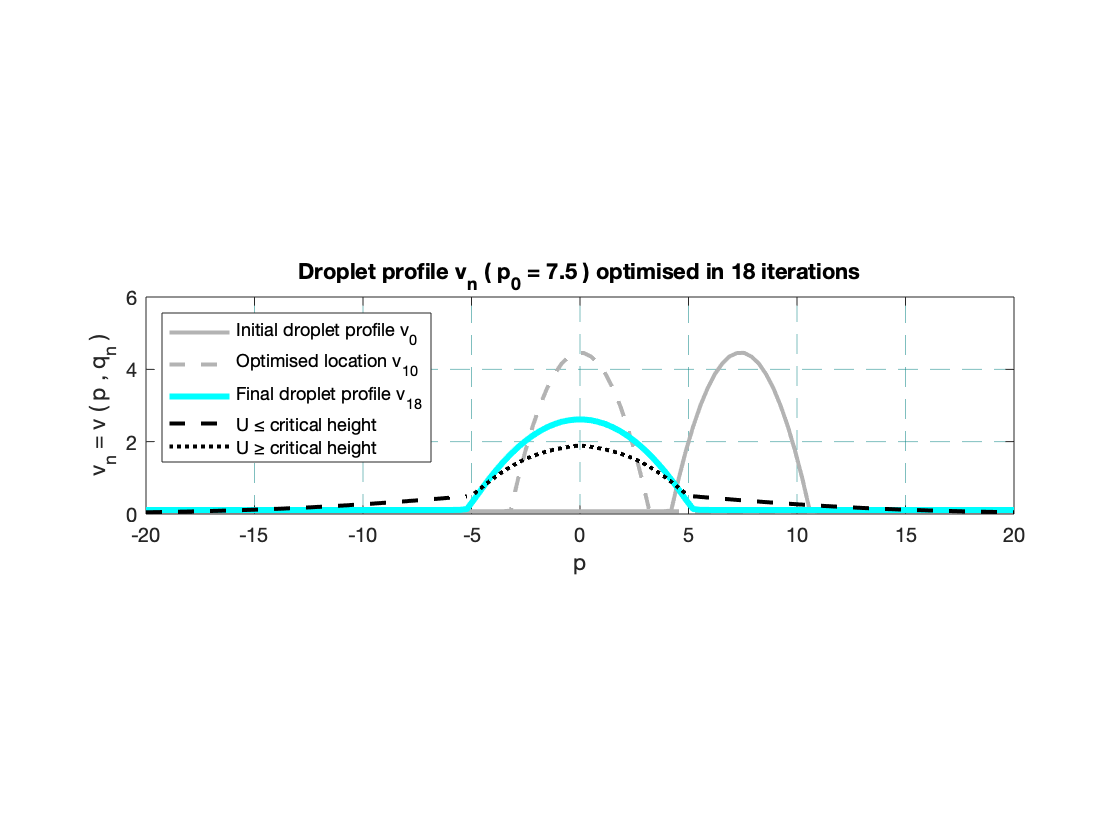

figure;
hold on
plot(X,H0_Possition,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H0_Disjoining,'--','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol_Disjoining,'c-','linewidth',3);
plot(X(1:a),h_region(1:a),'k--','linewidth',2);
plot(X(a+1:b),h_region(a+1:b),'k:','linewidth',2);
plot(X(b+1:end),h_region(b+1:end),'k--','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('v_n = v ( p , q_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile v_0',...
    'Optimised location v_{10}',...
    'Final droplet profile v_{18}',...
    'U ≤ critical height',...
    'U ≥ critical height',...
    'Location','northwest');
title('Droplet profile v_n ( p_0 = 7.5 ) optimised in 18 iterations');
hold off

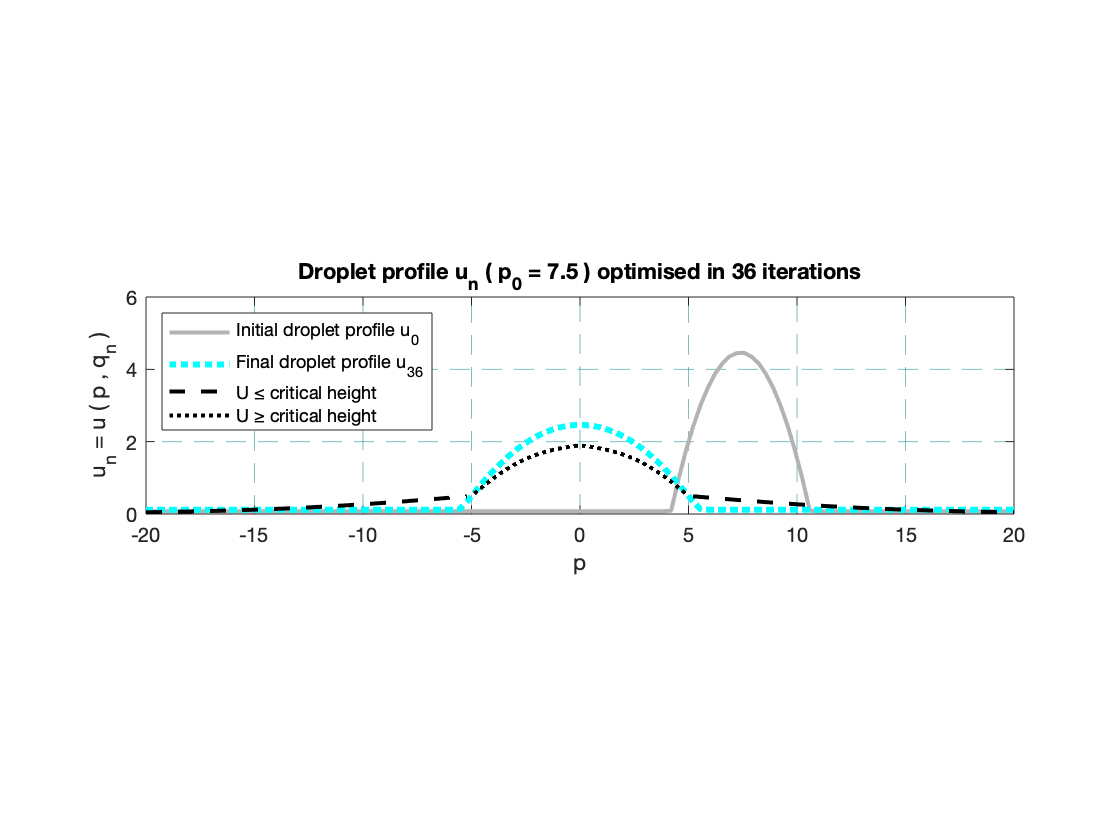


figure;
hold on
plot(X,H0_Possition,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol,'c:','linewidth',3);
plot(X(1:a),h_region(1:a),'k--','linewidth',2);
plot(X(a+1:b),h_region(a+1:b),'k:','linewidth',2);
plot(X(b+1:end),h_region(b+1:end),'k--','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('u_n = u ( p , q_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile u_0',...
    'Final droplet profile u_{36}',...
    'U ≤ critical height',...
    'U ≥ critical height',...
    'Location','northwest');
title('Droplet profile u_n ( p_0 = 7.5 ) optimised in 36 iterations');
hold off

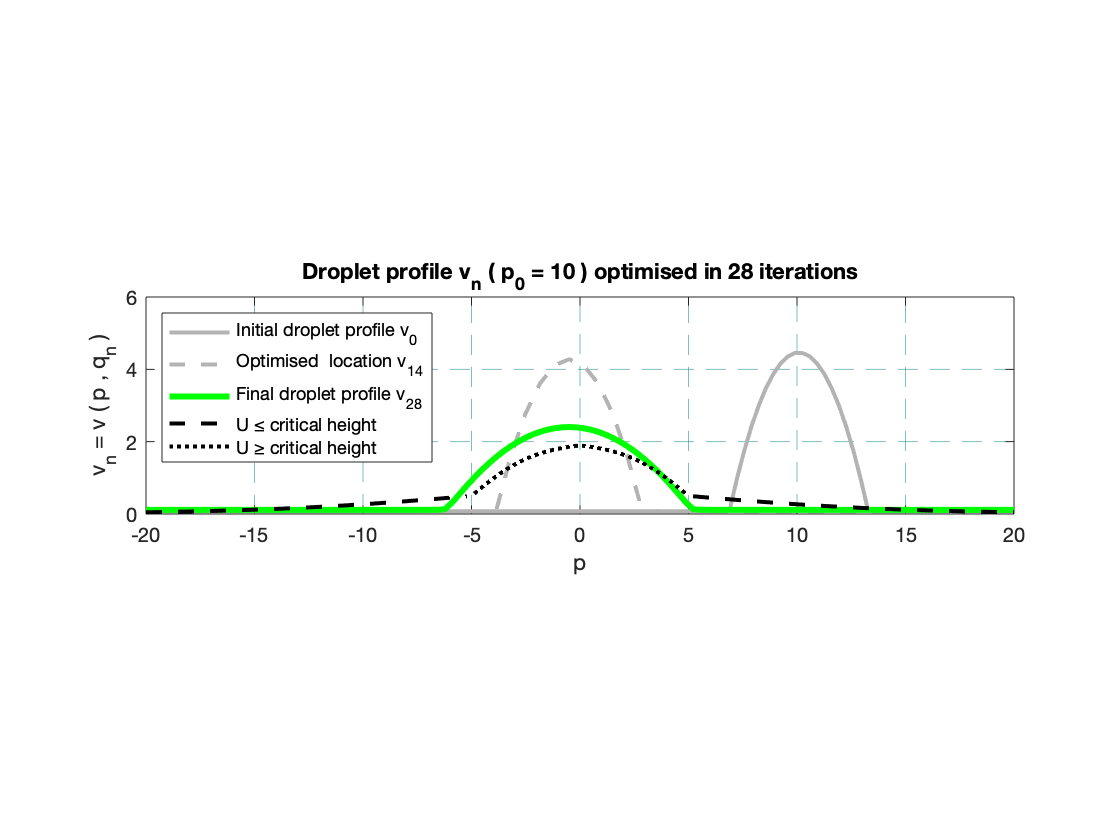



figure;
hold on
plot(X,H_2Possition,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_2Disjoining,'--','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol_2Disjoining,'g-','linewidth',3);
plot(X(1:a),h_region(1:a),'k--','linewidth',2);
plot(X(a+1:b),h_region(a+1:b),'k:','linewidth',2);
plot(X(b+1:end),h_region(b+1:end),'k--','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('v_n = v ( p , q_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile v_0',...
    'Optimised  location v_{14}',...
    'Final droplet profile v_{28}',...
    'U ≤ critical height',...
    'U ≥ critical height',...
    'Location','northwest');
title('Droplet profile v_n ( p_0 = 10 ) optimised in 28 iterations');
hold off

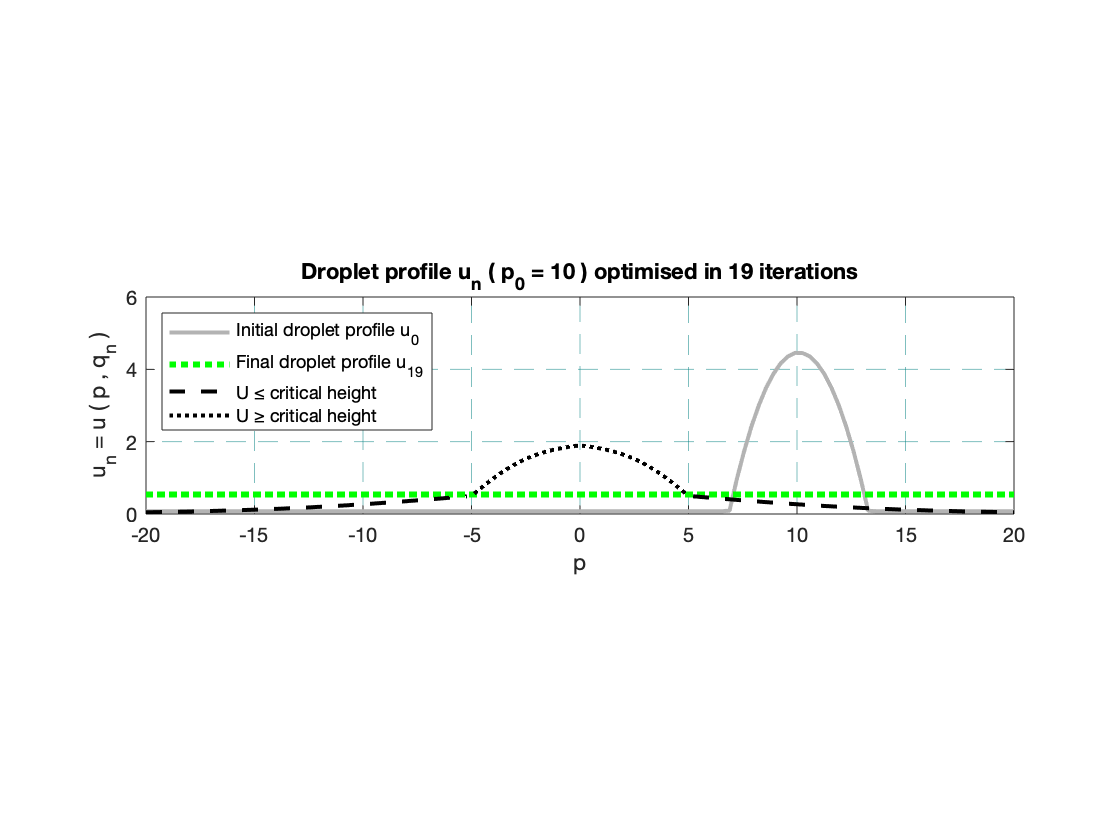


figure;
hold on
plot(X,H_2Possition,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol_2,'g:','linewidth',3);
plot(X(1:a),h_region(1:a),'k--','linewidth',2);
plot(X(a+1:b),h_region(a+1:b),'k:','linewidth',2);
plot(X(b+1:end),h_region(b+1:end),'k--','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('u_n = u ( p , q_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile u_0',...
    'Final droplet profile u_{19}',...
    'U ≤ critical height',...
    'U ≥ critical height',...
    'Location','northwest');
title('Droplet profile u_n ( p_0 = 10 ) optimised in 19 iterations');
hold off

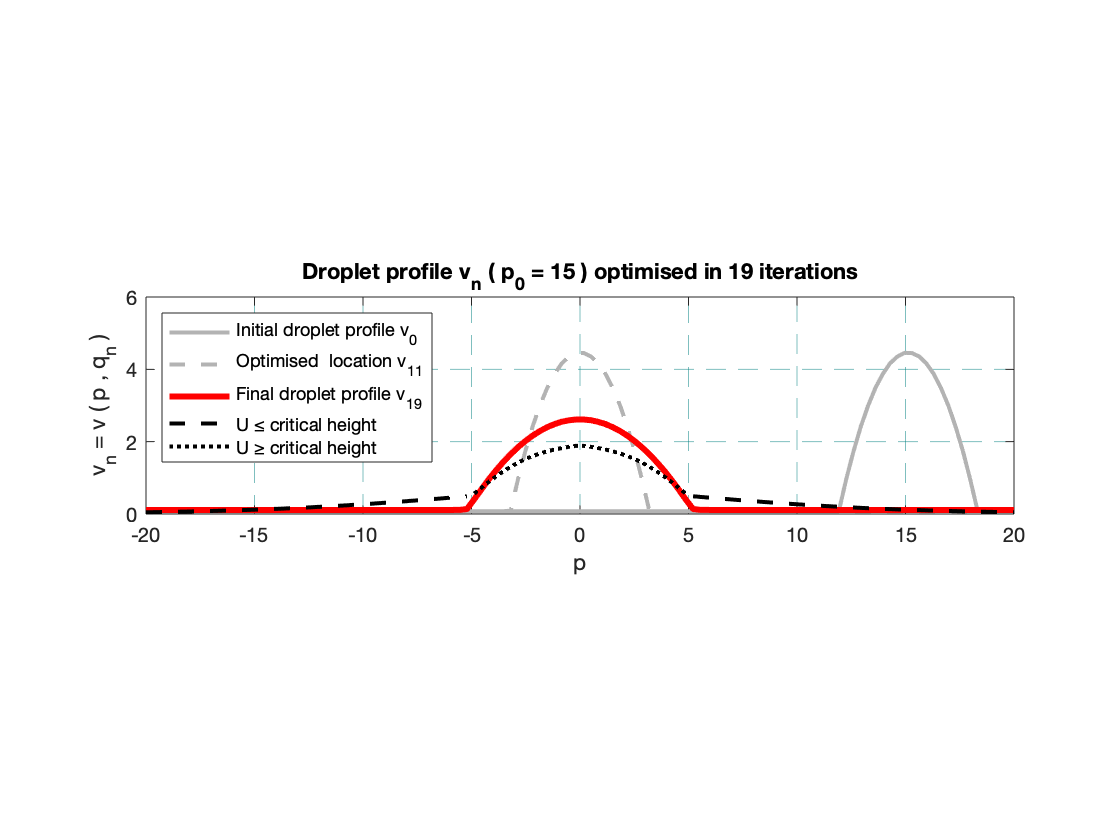



figure;
hold on
plot(X,H_1Possition,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_1Disjoining,'--','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol_1Disjoining,'r-','linewidth',3);
plot(X(1:a),h_region(1:a),'k--','linewidth',2);
plot(X(a+1:b),h_region(a+1:b),'k:','linewidth',2);
plot(X(b+1:end),h_region(b+1:end),'k--','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('v_n = v ( p , q_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile v_0',...
    'Optimised  location v_{11}',...
    'Final droplet profile v_{19}',...
    'U ≤ critical height',...
    'U ≥ critical height',...
    'Location','northwest');
title('Droplet profile v_n ( p_0 = 15 ) optimised in 19 iterations');
hold off

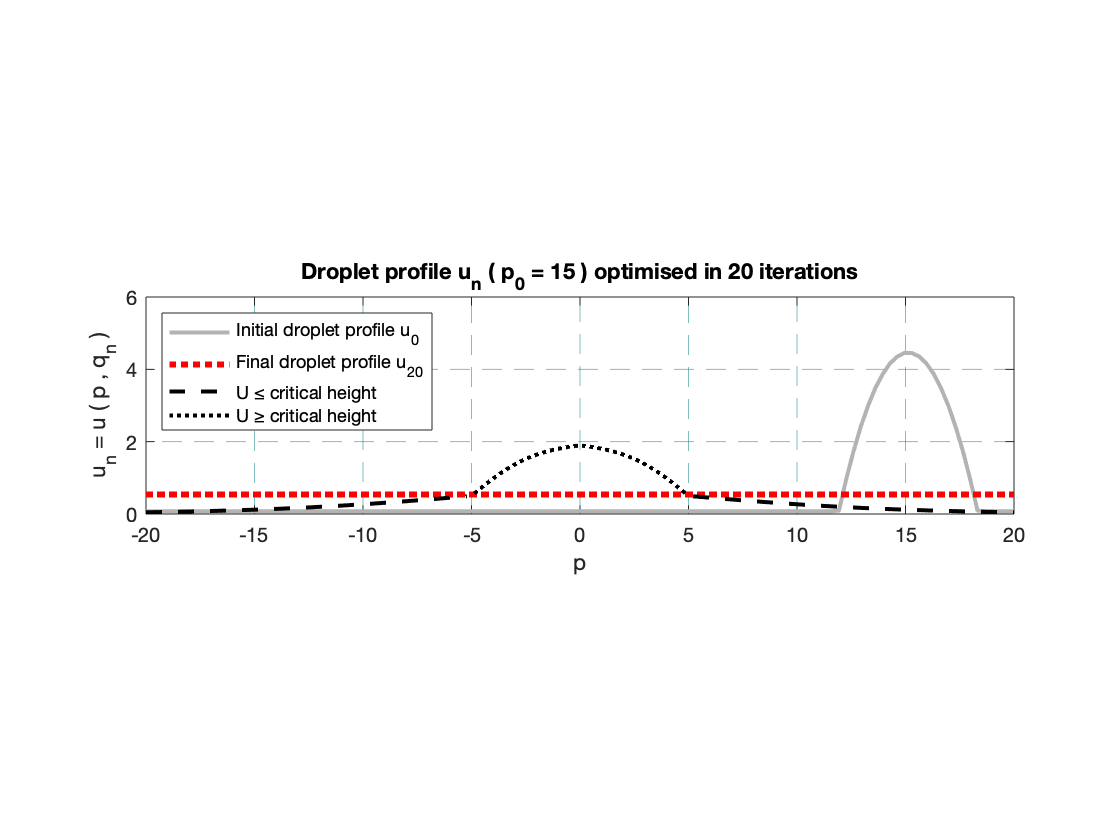


figure;
hold on
plot(X,H_1Possition,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol_1,'r:','linewidth',3);
plot(X(1:a),h_region(1:a),'k--','linewidth',2);
plot(X(a+1:b),h_region(a+1:b),'k:','linewidth',2);
plot(X(b+1:end),h_region(b+1:end),'k--','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('u_n = u ( p , q_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile u_0',...
    'Final droplet profile u_{20}',...
    'U ≤ critical height',...
    'U ≥ critical height',...
    'Location','northwest');
title('Droplet profile u_n ( p_0 = 15 ) optimised in 20 iterations');
hold off

**Joint Figures**

Fig. 1

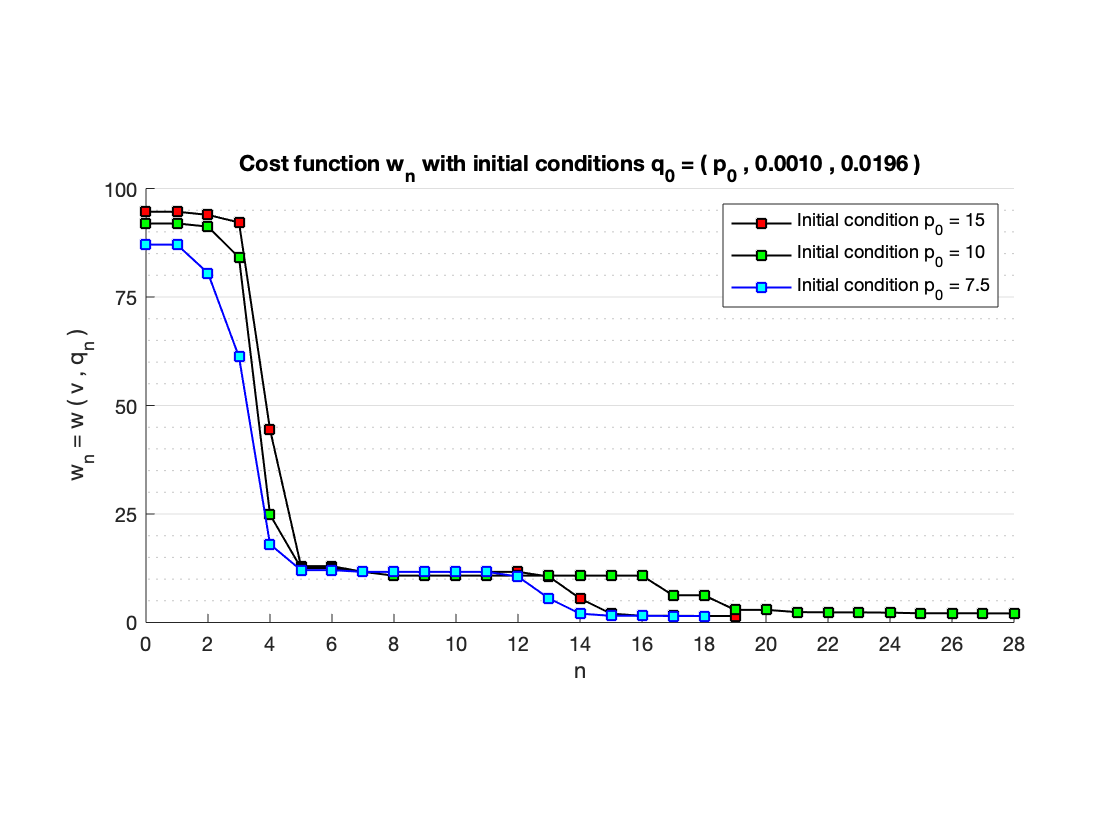

figure;
hold on
plot(0:19,History1_1,'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:28,History1_2,'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:18,History1,'b-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
ylabel('w_n = w ( v , q_n )');
xlabel('n');
legend('Initial condition p_0 = 15','Initial condition p_0 = 10','Initial condition p_0 = 7.5','Location','northeast');
title('Cost function w_n with initial conditions q_0 = ( p_0 , 0.0010 , 0.0196 )');
xlim([0 28]);
ylim([0 100]);
set(gca,'xtick',0:2:100);
set(gca,'ytick',0:25:500);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
pbaspect([2 1 1]);
box off
hold off

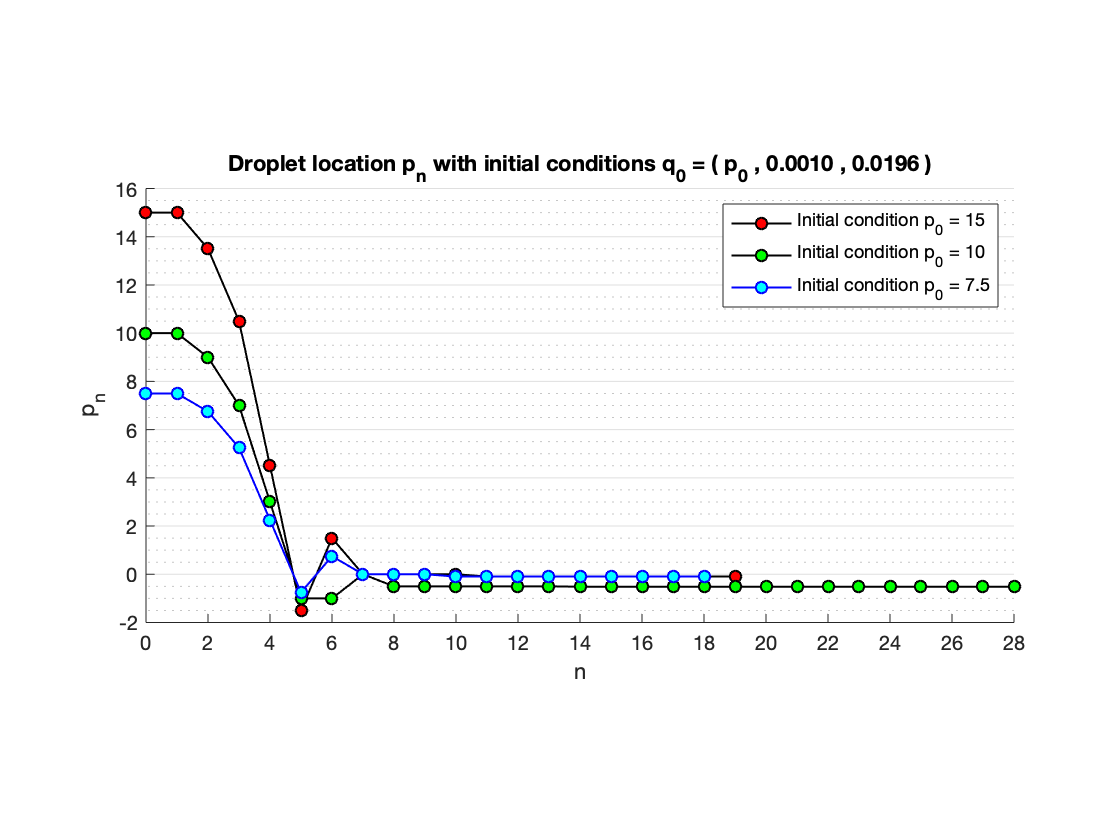


figure;
hold on
plot(0:19,history1_1(:,1),'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:28,history1_2(:,1),'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:18,history1(:,1),'b-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
ylabel('p_n');
xlabel('n');
legend('Initial condition p_0 = 15','Initial condition p_0 = 10','Initial condition p_0 = 7.5','Location','northeast');
title('Droplet location p_n with initial conditions q_0 = ( p_0 , 0.0010 , 0.0196 )');
xlim([0 28]);
ylim([-2 16]);
set(gca,'xtick',0:2:100);
set(gca,'ytick',-4:2:500);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
pbaspect([2 1 1]);
box off
hold off

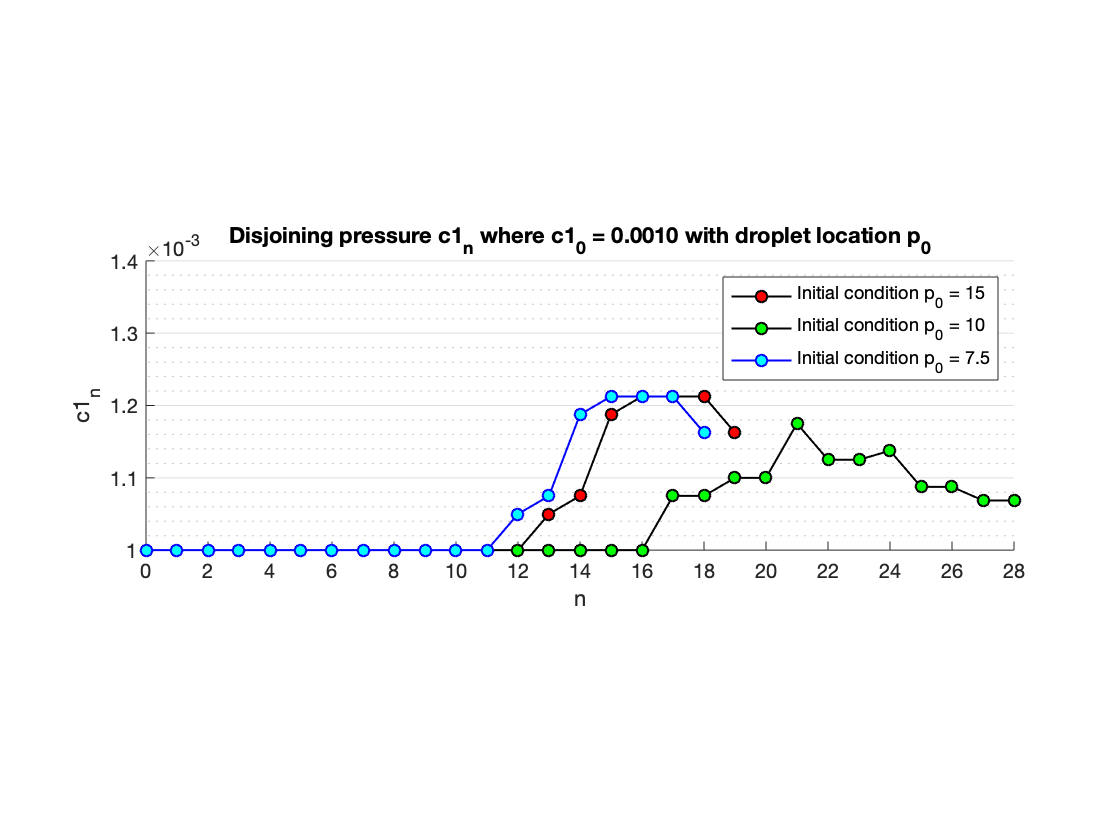


figure;
hold on
plot(0:19,history1_1(:,2),'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:28,history1_2(:,2),'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:18,history1(:,2),'b-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
pbaspect([3 1 1]);
ylabel('c1_n');
xlabel('n');
title('Disjoining pressure c1_n where c1_0 = 0.0010 with droplet location p_0');
legend('Initial condition p_0 = 15','Initial condition p_0 = 10','Initial condition p_0 = 7.5','Location','northeast');
xlim([0 28]);
ylim([.001 .0014]);
set(gca,'xtick',0:2:100);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
hold off

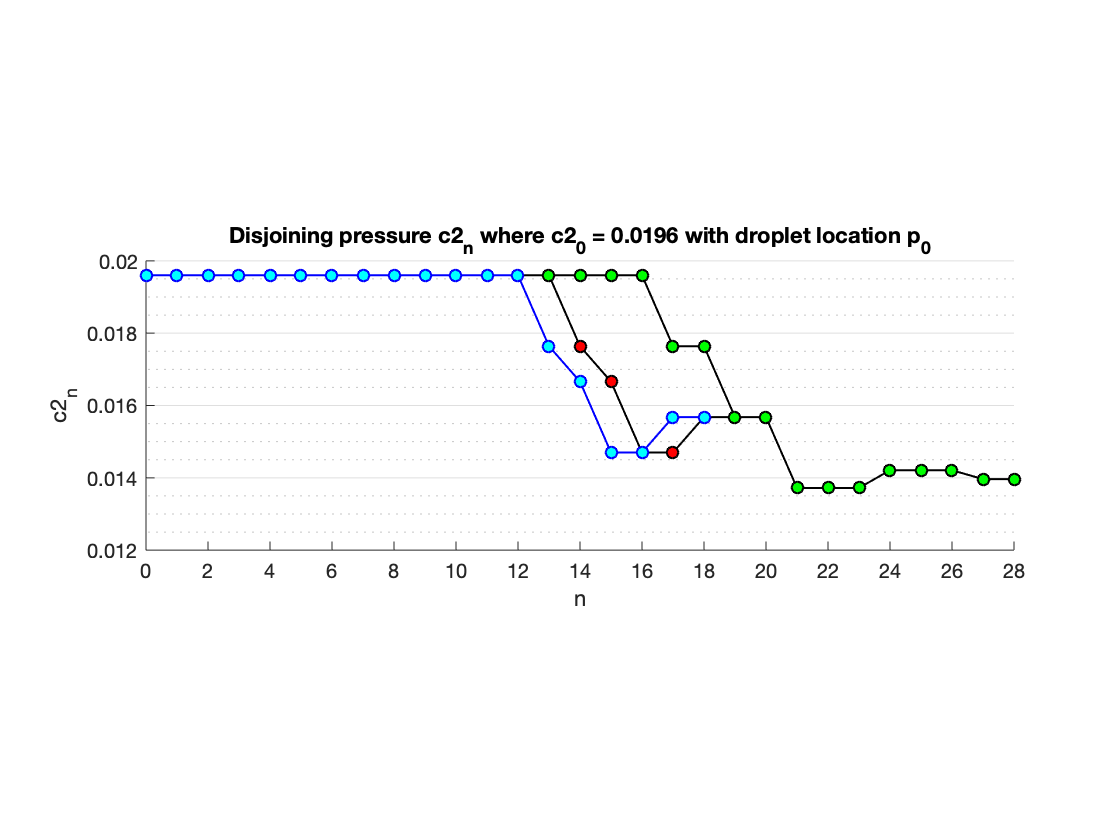


figure;
hold on
plot(0:19,history1_1(:,3),'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:28,history1_2(:,3),'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:18,history1(:,3),'b-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
pbaspect([3 1 1]);
ylabel('c2_n');
xlabel('n');
title('Disjoining pressure c2_n where c2_0 = 0.0196 with droplet location p_0');
xlim([0 28]);
ylim([0.012 .02]);
set(gca,'xtick',0:2:100);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
hold off

**Joint Figures**

Fig. 1

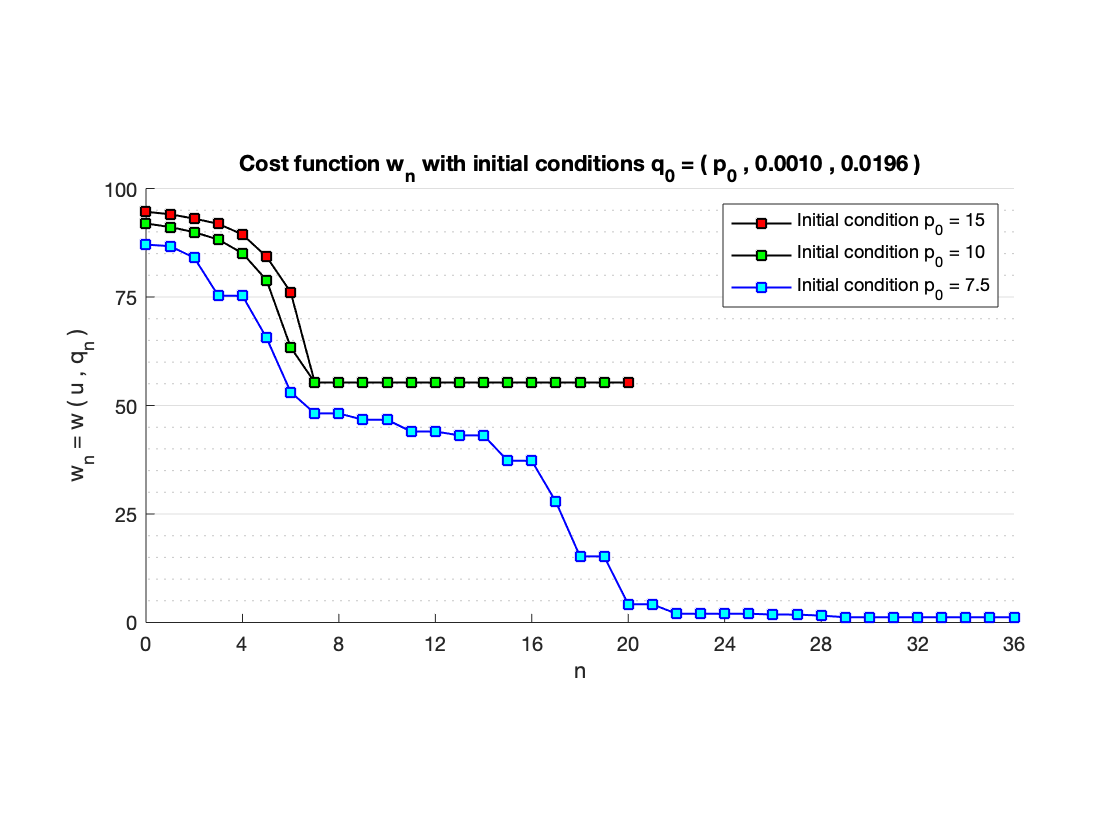

figure;
hold on
plot(0:20,History_1,'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:19,History_2,'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:36,History,'b-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
ylabel('w_n = w ( u , q_n )');
xlabel('n');
legend('Initial condition p_0 = 15','Initial condition p_0 = 10','Initial condition p_0 = 7.5','Location','northeast');
title('Cost function w_n with initial conditions q_0 = ( p_0 , 0.0010 , 0.0196 )');
xlim([0 36]);
ylim([0 100]);
set(gca,'xtick',0:4:100);
set(gca,'ytick',0:25:500);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
pbaspect([2 1 1]);
box off
hold off

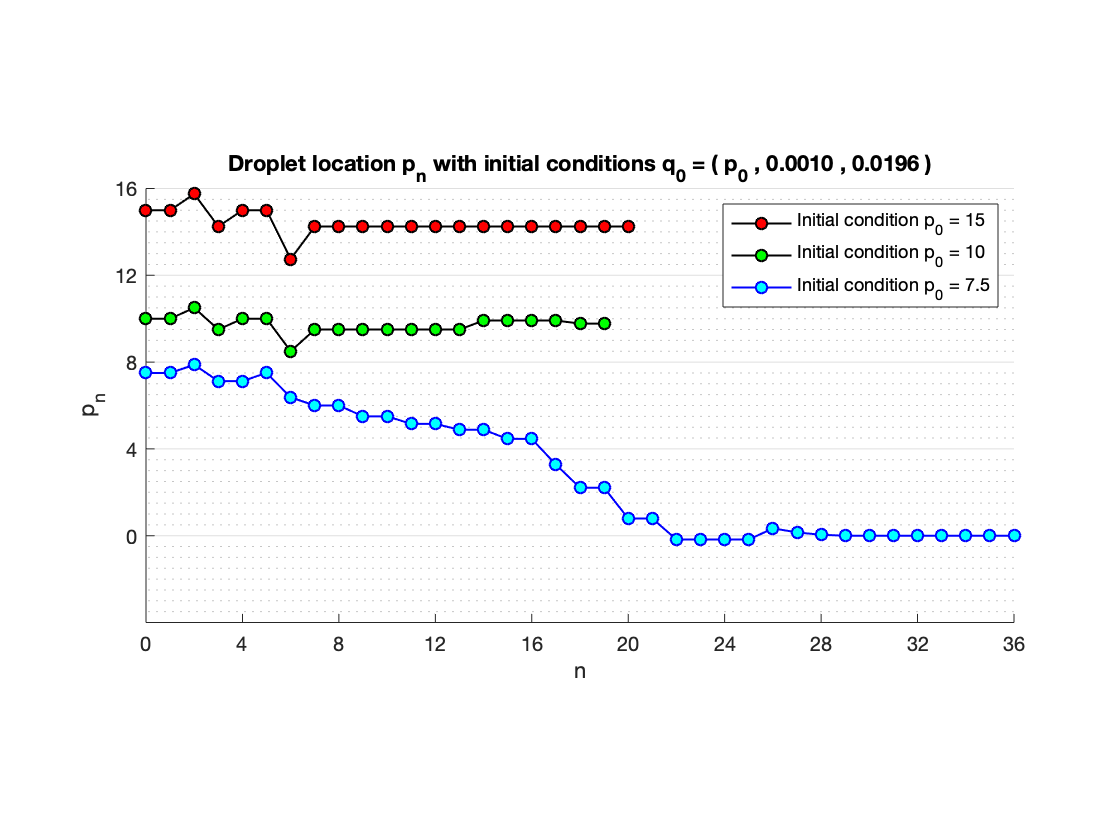


figure;
hold on
plot(0:20,history_1(1,:),'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:19,history_2(1,:),'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:36,history(1,:),'b-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
ylabel('p_n');
xlabel('n');
legend('Initial condition p_0 = 15','Initial condition p_0 = 10','Initial condition p_0 = 7.5','Location','northeast');
title('Droplet location p_n with initial conditions q_0 = ( p_0 , 0.0010 , 0.0196 )');
xlim([0 36]);
ylim([-4 16]);
set(gca,'xtick',0:4:100);
set(gca,'ytick',0:4:500);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
pbaspect([2 1 1]);
box off
hold off

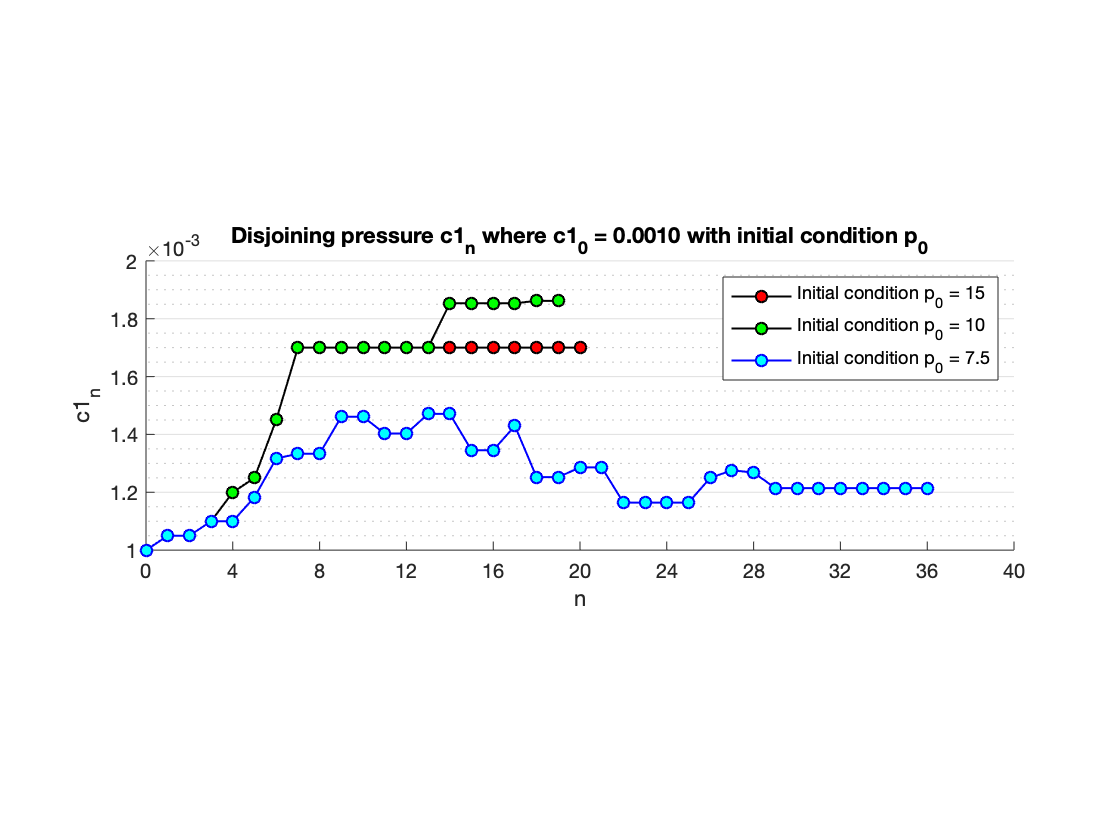


figure;
hold on
plot(0:20,history_1(2,:),'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:19,history_2(2,:),'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:36,history(2,:),'b-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
pbaspect([3 1 1]);
ylabel('c1_n');
xlabel('n');
title('Disjoining pressure c1_n where c1_0 = 0.0010 with initial condition p_0');
legend('Initial condition p_0 = 15','Initial condition p_0 = 10','Initial condition p_0 = 7.5','Location','northeast');
xlim([0 40]);
ylim([.001 .002]);
set(gca,'xtick',0:4:100);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
hold off

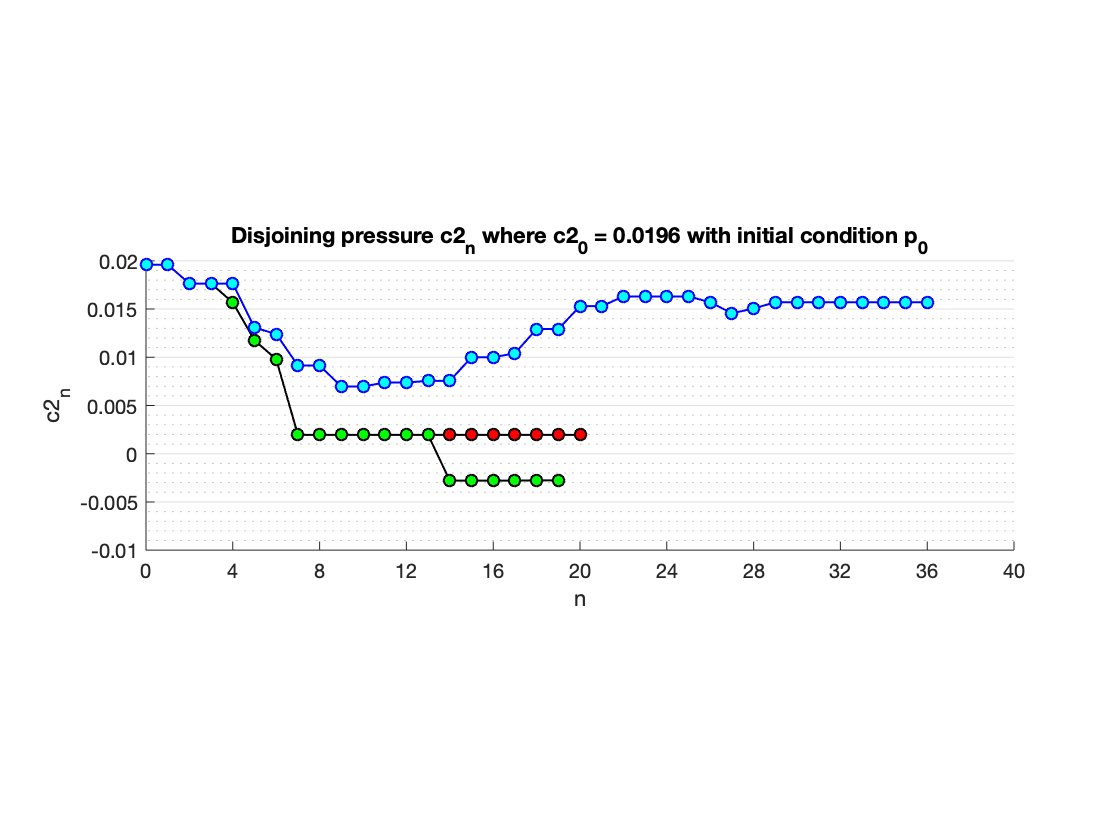


figure;
hold on
plot(0:20,history_1(3,:),'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:19,history_2(3,:),'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:36,history(3,:),'b-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
pbaspect([3 1 1]);
ylabel('c2_n');
xlabel('n');
title('Disjoining pressure c2_n where c2_0 = 0.0196 with initial condition p_0');
set(gca,'xtick',0:4:100);
xlim([0 40]);
ylim([-.01 .02]);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
hold off